# Test della funzione matRot

## Test sugli assi coordinati

Si vuole testare la funzione matRot per i tre assi coordinati. 

Per fare ciò si definisce una variabile simbolica che rappresenta l'angolo di rotazione.

syms theta real

### Asse coordinato X

x = [1; 0; 0];
Rx = matRot(x, theta)

$$Rx = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & \cos\left(\theta \right) & -\sin\left(\theta \right)\\ 0 & \sin\left(\theta \right) & \cos\left(\theta \right) \end{array}\right)$$

### Asse coordinato Y

y = [0; 1; 0];
Ry = matRot(y, theta)

$$Ry = \left(\begin{array}{ccc} \cos\left(\theta \right) & 0 & \sin\left(\theta \right)\\ 0 & 1 & 0\\ -\sin\left(\theta \right) & 0 & \cos\left(\theta \right) \end{array}\right)$$

### Asse coordinato Z

z = [0; 0; 1];
Rz = matRot(z, theta)

$$Rz = \left(\begin{array}{ccc} \cos\left(\theta \right) & -\sin\left(\theta \right) & 0\\ \sin\left(\theta \right) & \cos\left(\theta \right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

## Test grafico

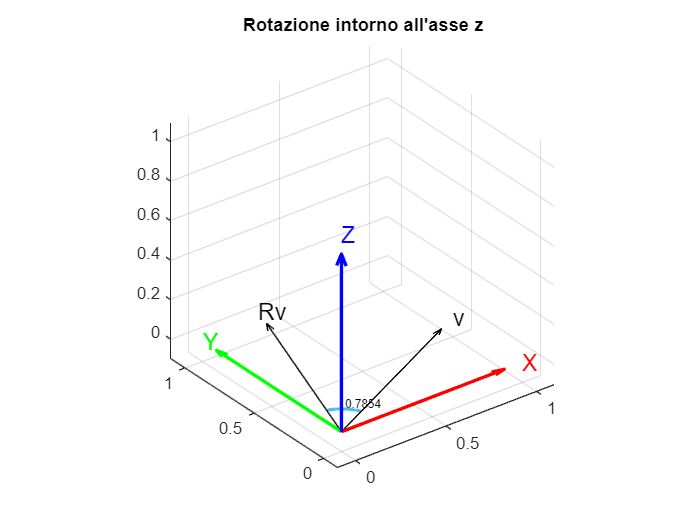

% Assi
x = [1 0 0];
y = [0 1 0];
z = [0 0 1];

% Plot degli assi
quiver3(0, 0, 0, x(1), x(2), x(3), 'r', 'LineWidth', 2);
hold on;
quiver3(0, 0, 0, y(1), y(2), y(3), 'g', 'LineWidth', 2);
quiver3(0, 0, 0, z(1), z(2), z(3), 'b', 'LineWidth', 2);

text(x(1), x(2), x(3), 'X', 'FontSize', 14, 'Color', 'r');
text(y(1), y(2), y(3), 'Y', 'FontSize', 14, 'Color', 'g');
text(z(1), z(2), z(3), 'Z', 'FontSize', 14, 'Color', 'b');

% Rotazione di un vettore
vec1 = [1; 0.5; 0];
angle = pi/4;
R = matRot([0 0 1], angle);
vec2 = R*vec1;

% Plot del vettore ruotato
quiver3(0, 0, 0, vec1(1), vec1(2), vec1(3), 'k');
quiver3(0, 0, 0, vec2(1), vec2(2), vec2(3), 'k');

text(vec1(1), vec1(2), vec1(3), 'v', 'FontSize', 14, 'Color', 'k');
text(vec2(1), vec2(2), vec2(3), 'Rv', 'FontSize', 14, 'Color', 'k');

% Plot dell'angolo
drawAngle(vec1, vec2)

% limiti assi e label
grid on
axis equal;
xlim([-0.1 1.1]);
ylim([-0.1 1.1]);
zlim([-0.1 1.1]);
title('Rotazione intorno all''asse z');